# Reacting and Conserved Moieties Tutorial

## Reproducing Results from Rahou et al., JTB 2025

## Authors

Hadjar Rahou

Ronan M.T. Fleming

Affiliation:

University of Galway, Ireland

## Overview

This Live Script reproduces the conserved and reacting moiety workflow described in:

- **Ghaderi et al. (2020)** – Structural conserved moiety splitting

- **Rahou et al. (2025)** – Characterisation of conserved and reacting moieties

The tutorial follows the theoretical structure of Rahou et al. (2025):

- Stoichiometric framework and null spaces

- Directed atom transition multigraph (dATM)

- Atom transition graph (ATG)

- Conserved moieties

- Bond graph integration (BIG)

- Reacting moieties via minimum set cover

- Moiety graph construction

# Prerequisites

- MATLAB (R2020 or newer recommended)

- Optimization Toolbox

- The COBRA Toolbox (0), to be obtained here: [https://opencobra.github.io/cobratoolbox/stable/installation.html](https://opencobra.github.io/cobratoolbox/stable/installation.html)

# 1. Environment Check

This ensures required toolboxes are available.

%% 1. Environment check

% tf = license('test','Statistics_Toolbox')
% 
% tf =
% 
%      0
% 
% tf = license('test','Optimization_Toolbox')
% 
% tf =
% 
%      0

% assert(~isempty(ver('optim')), ...
%     'Optimization Toolbox is required.')
% 
% disp('Environment OK.')

# 2. Load Model

We load a genome-scale metabolic model.

%% 2. Load metabolic model

% modelFileName = 'Recon3D_301.mat';
% modelDirectory = '~/cobratoolbox/test/models/mat';
% modelPath = [modelDirectory filesep modelFileName];
% 
% model = readCbModel(modelPath);
% 
% disp('Model loaded.')
% Automatically detect COBRA installation directory
cobraDir = fileparts(which('initCobraToolbox'));

modelDirectory = fullfile(cobraDir,'test','models','mat');
modelPath = fullfile(modelDirectory,'Recon3D_301.mat');

Environment OK.



model = readCbModel(modelPath);

disp('Model loaded successfully.')

# 3. Extract Subnetwork

For clarity and reproducibility, we extract the small example network used in Ghaderi et al. (2020).

%% 3. Extract subnetwork

rxnList = {'r0317'; 'ACONTm'; 'r0426'};
subModel = extractSubNetwork(model, rxnList);

mets = subModel.mets;
rxns = subModel.rxns;


Each model.subSystems{x} has been changed to a character array.


N = full(subModel.S);


Model loaded successfully.


fprintf('Stoichiometric matrix size: %dx%d\n', size(N,1), size(N,2));

# 4. Stoichiometric Framework (Paper Section 2)

The left null space of N defines conserved quantities.

%% 4. Stoichiometric null space

r = rank(N);
nullity = size(N,1) - r;

fprintf('Rank(N) = %d\n', r);
fprintf('Left null space dimension = %d\n', nullity);

# 5. Atom and Bond Transition Multigraphs (Paper Section 3)

We now construct:

- Directed Atom Transition Multigraph (dATM)

- Bond Graph (BG)

%% Configure tutorial paths

% Get path of this live script
tutorialDir = fileparts(which('tutorial_conservedAndReactingMoieties'))

Stoichiometric matrix size: 4x3



% Move to tutorial folder
cd(tutorialDir);

% Local rxnFiles folder
atomMappedDir = fullfile('data','rxnFiles');

if ~isfolder(atomMappedDir)
    error('rxnFiles folder not found in tutorial directory.')

Rank(N) = 2


end

Left null space dimension = 2



disp('Tutorial paths configured correctly.')
%% 5. Build atom and bond transition multigraphs

options.directed = 0;
options.sanityChecks = 1;

% atomMappedDir = '~/drive/polimer/data/reactingMoieties/rxnFile/';

[dATM, metAtomMappedBool, rxnAtomMappedBool, ...
    M2Ai, Ti2R, dATME, BG ,dBTM, ...
    M2BiE, M2BiW, BTi2R, TiE] = ...
    buildAtomAndBondTransitionMultigraph(subModel, atomMappedDir, options);

disp('dATM and BG constructed.')

# 6. Visualise Bond Graph (Optional)

This visualisation shows bond connectivity at the molecular level.

%% 6. Visualise Bond Graph

figure
plot(BG,'Layout','layered')
title('Bond Instance Graph (BIG)')

Tutorial paths configured correctly.


# 7. Identify Conserved and Reacting Moieties

## (Core Algorithm – Rahou 2025)

This step computes:

- Conserved moieties (left-null-space structured patterns)

- Reacting moieties (non-conserved bond structures)

%% 7. Identify conserved and reacting moieties

options.sanityChecks = 0;

[arm, moietyFormulae, reacting] = ...
    identifyConservedReactingMoieties(subModel, BG, dATM, options);

disp('Moiety identification complete.')

# 8. Conserved Moieties (Paper Section 4)

## 8.1 Moiety Basis Matrix LLL

%% 8.1 Conserved moiety matrix

Checking quality of RXN files...
RXN files available for 4 reactions.

RXN file with atom mapping summary:
4 metabolites in model
4 metabolites in atom mapped subset of model
3 reactions in model
3 internal reactions in model
3 reactions in atom mapped subset of model
3 RXN files parsed.
3 RXN files with the number of atom conserved between substrates and products.
3 RXN files matching stoichiometry of the model.
0 RXN files matching stoichiometry of the model, upto protons.
0 RXN files not matching stoichiometry of model, even ignoring protons.
3 RXN files with substrate transition numbers ordered 1:q.
3 RXN files with product transition numbers ordered 1:q.
3 RXN files with matching numbering of atoms between substrates and products.
3 RXN files with matching elements between substrates and products.
Generating atom transition network for reactions with atom mappings...
0	rows of Ti = incidence(dATM), with only one negative entry and no positive entry.
0	rows of Ti = incidence(dATM),


L = full(arm.L);

dATM and BG constructed.



disp('Conserved moiety matrix L:')
disp(L)

figure
spy(L * N)
title('Verification: L*N = 0')

If the matrix is zero → conservation holds.

## 8.2 Moiety Transition Graph (MTG)

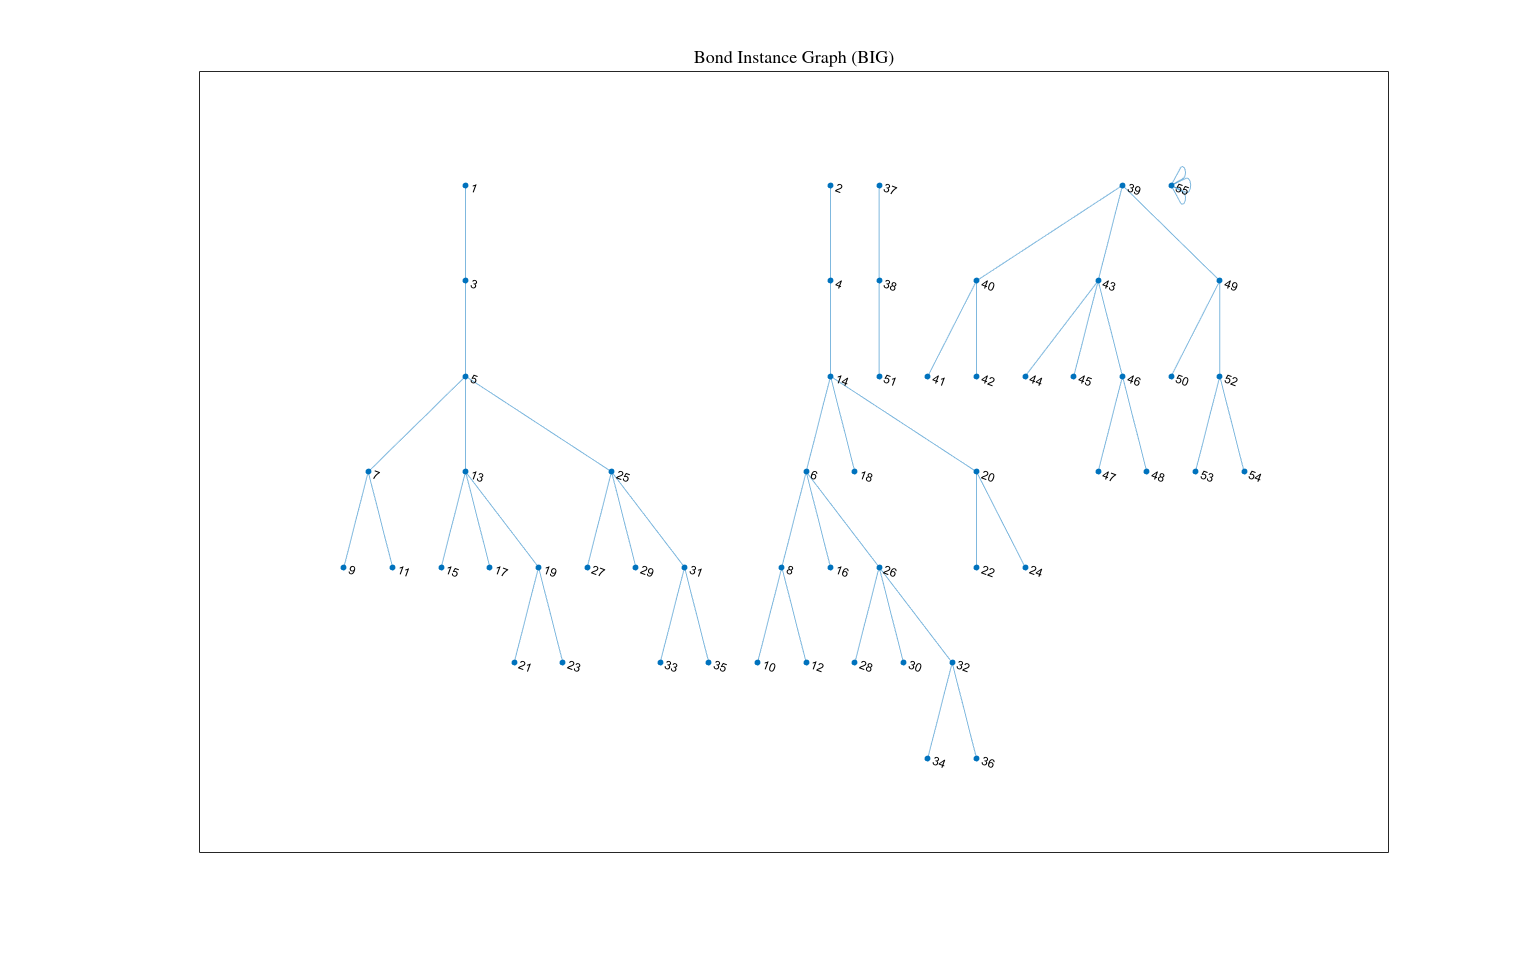

%% 8.2 Moiety Transition Graph


figure
plot(arm.MTG)
title('Moiety Transition Graph (MTG)')

# 9. Bond Integration (Paper Section 5)

Bond-level information is integrated into conserved structure.

%% 9. Molecular graphs of moieties

for i = 1:length(arm.MG)
    figure
    plot(arm.MG{i})
    title(sprintf('Moiety %d molecular graph', i))
end

# 10. Reacting Moieties (Paper Section 6 – Core Contribution)

Reacting bonds are those not part of conserved bond patterns.

## 10.1 Selected Minimal Reaction Set

%% 10.1 Minimal reaction set

Moiety identification complete.



disp('Selected reactions covering reacting bonds:')
disp(reacting.selectedReactionNames)

## 10.2 Condensed Reacting Bond Graph

%% 10.2 Condensed Reacting Bond Graph

figure
plot(reacting.Condensed_RBG)
title('Condensed Reacting Bond Graph')

Conserved moiety matrix L:


## 10.3 Reacting Moiety Summary

This reports the number of reacting bonds per selected reaction.

%% 10.3 Reacting moiety summary

     1     1     1     0
     0     1     1     1



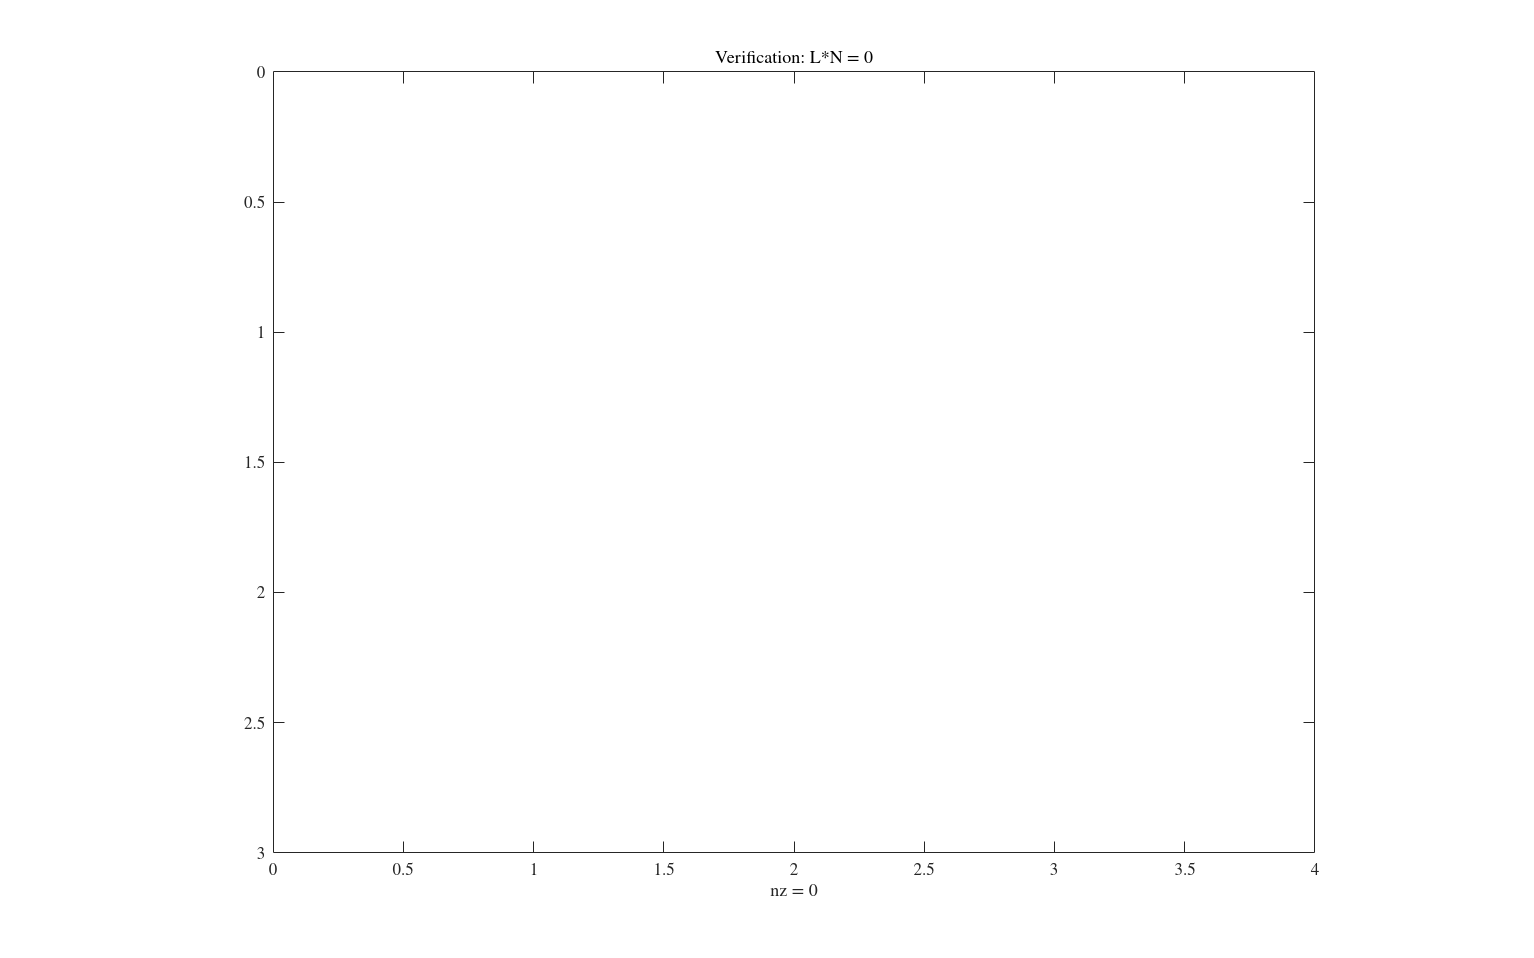


rxnList = reacting.selectedReactionNames;

summary = table('Size',[numel(rxnList) 2], ...

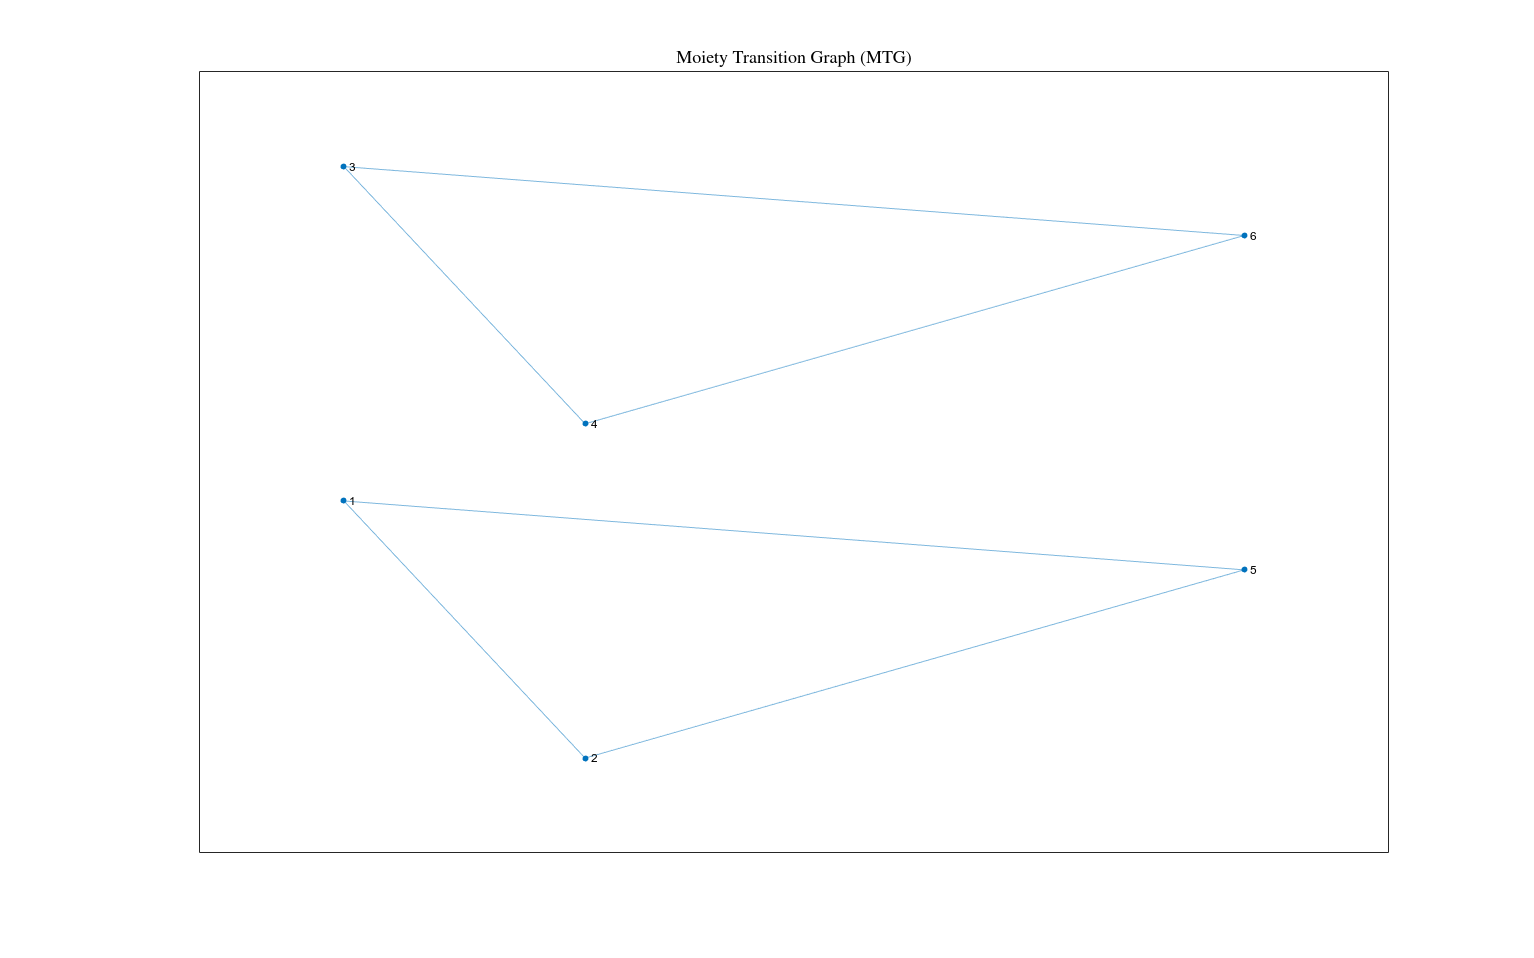

    'VariableTypes',["string","double"], ...
    'VariableNames',["Reaction","NumReactingBonds"]);

for k = 1:numel(rxnList)
    summary.Reaction(k) = string(rxnList{k});
    summary.NumReactingBonds(k) = ...
        length(reacting.ReactMoietySets{k});
end


disp(summary)

## 10.4 Reacting Moiety Type Summary (Formed vs Broken)

We now distinguish bond formation and bond cleavage events.

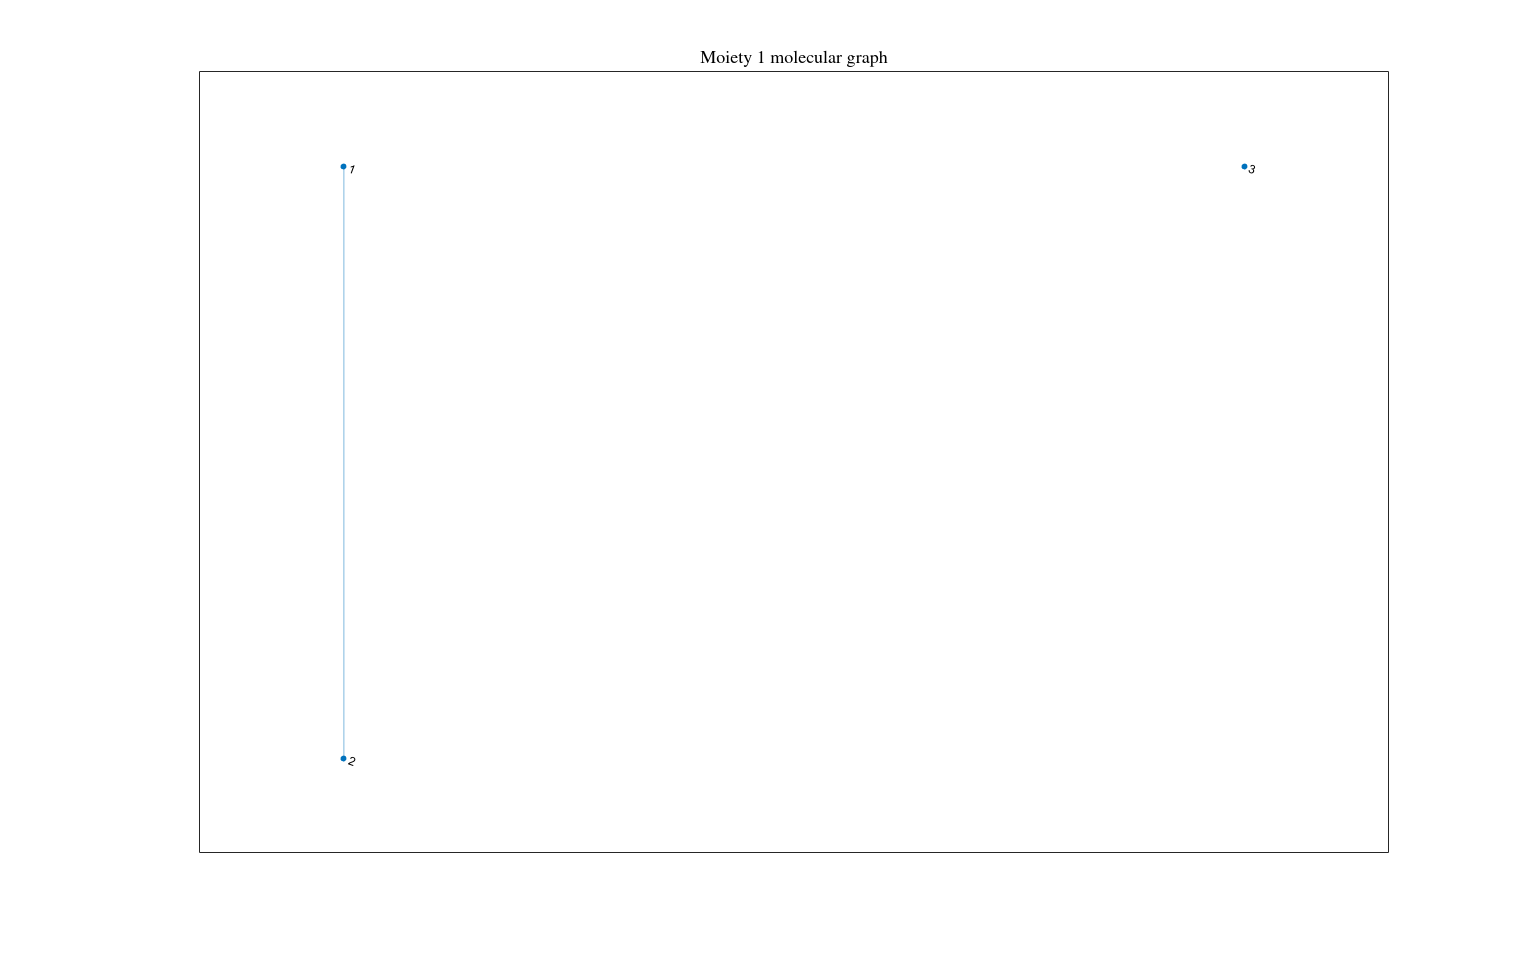

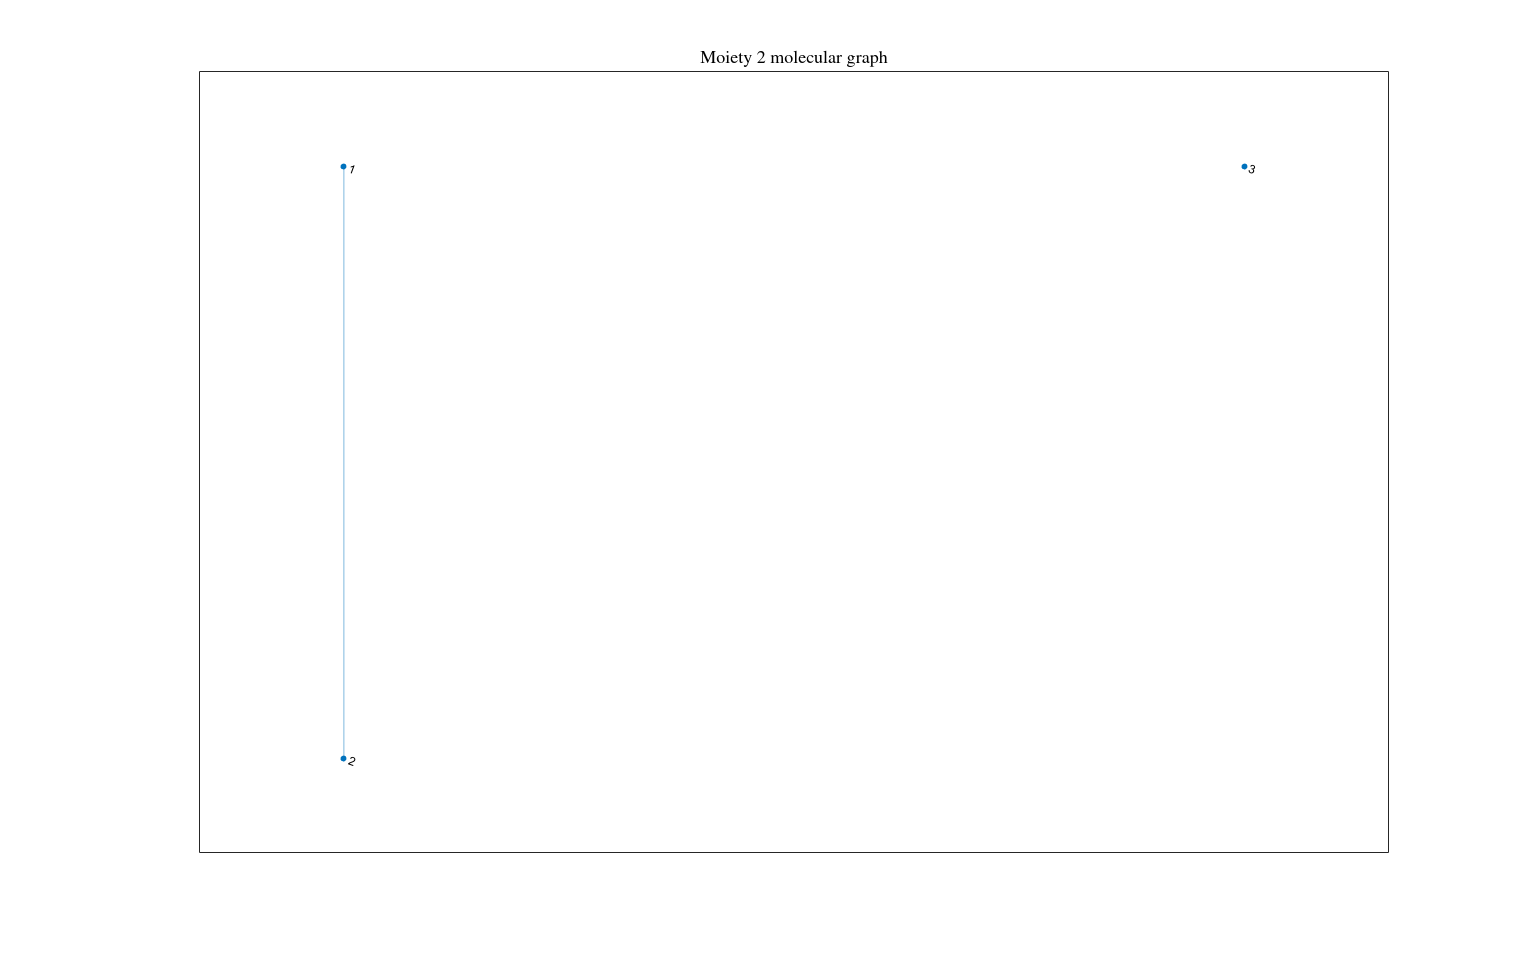

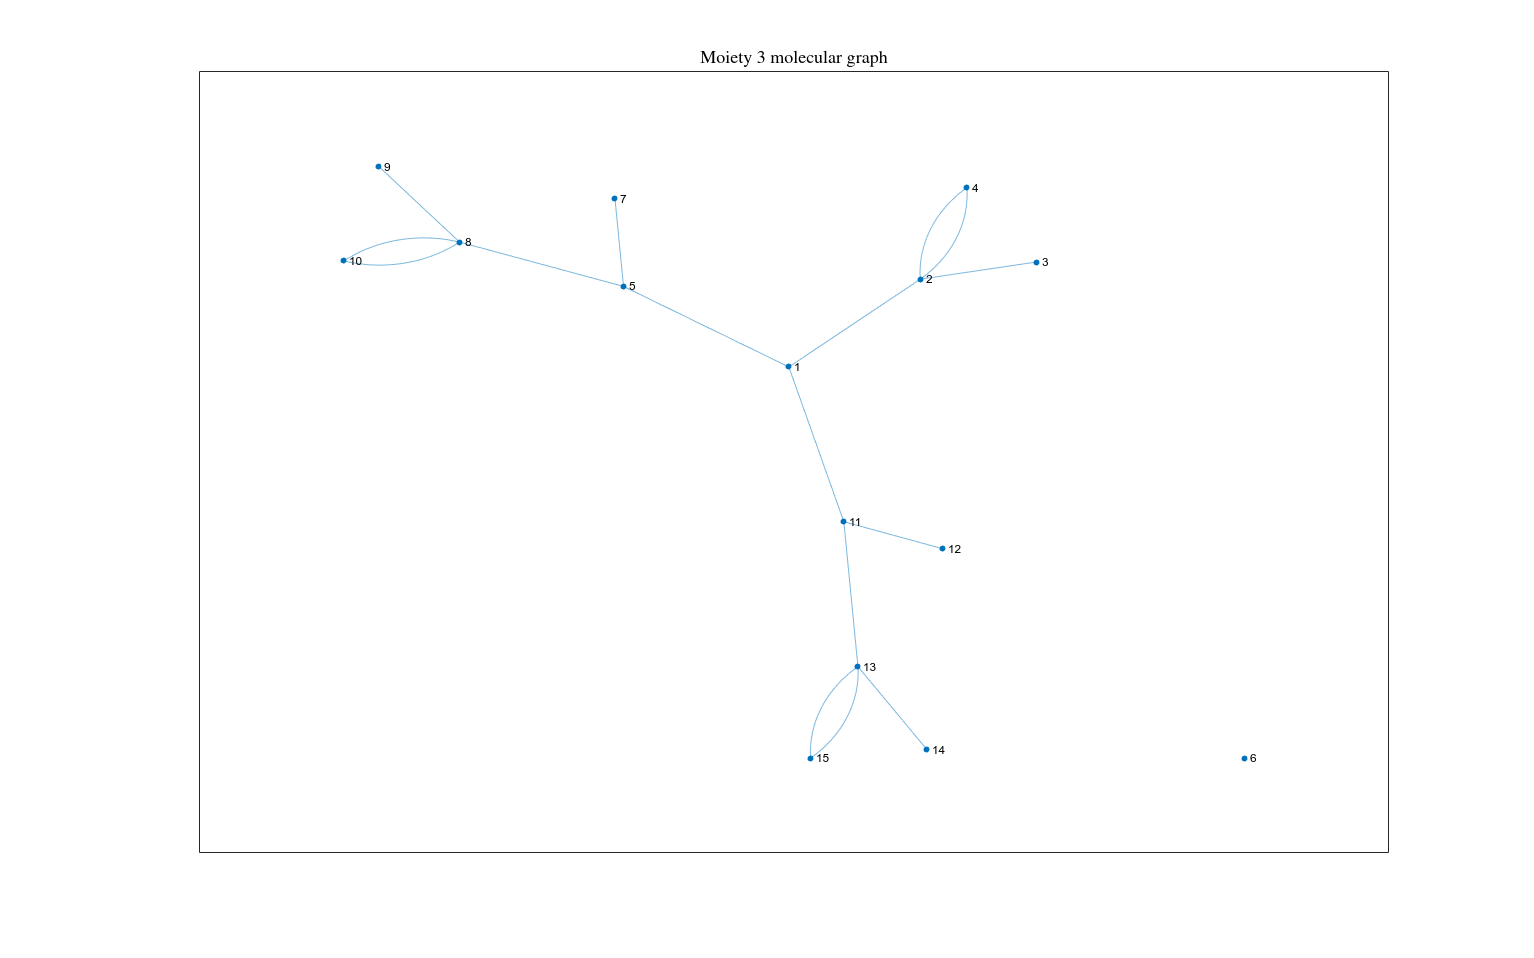

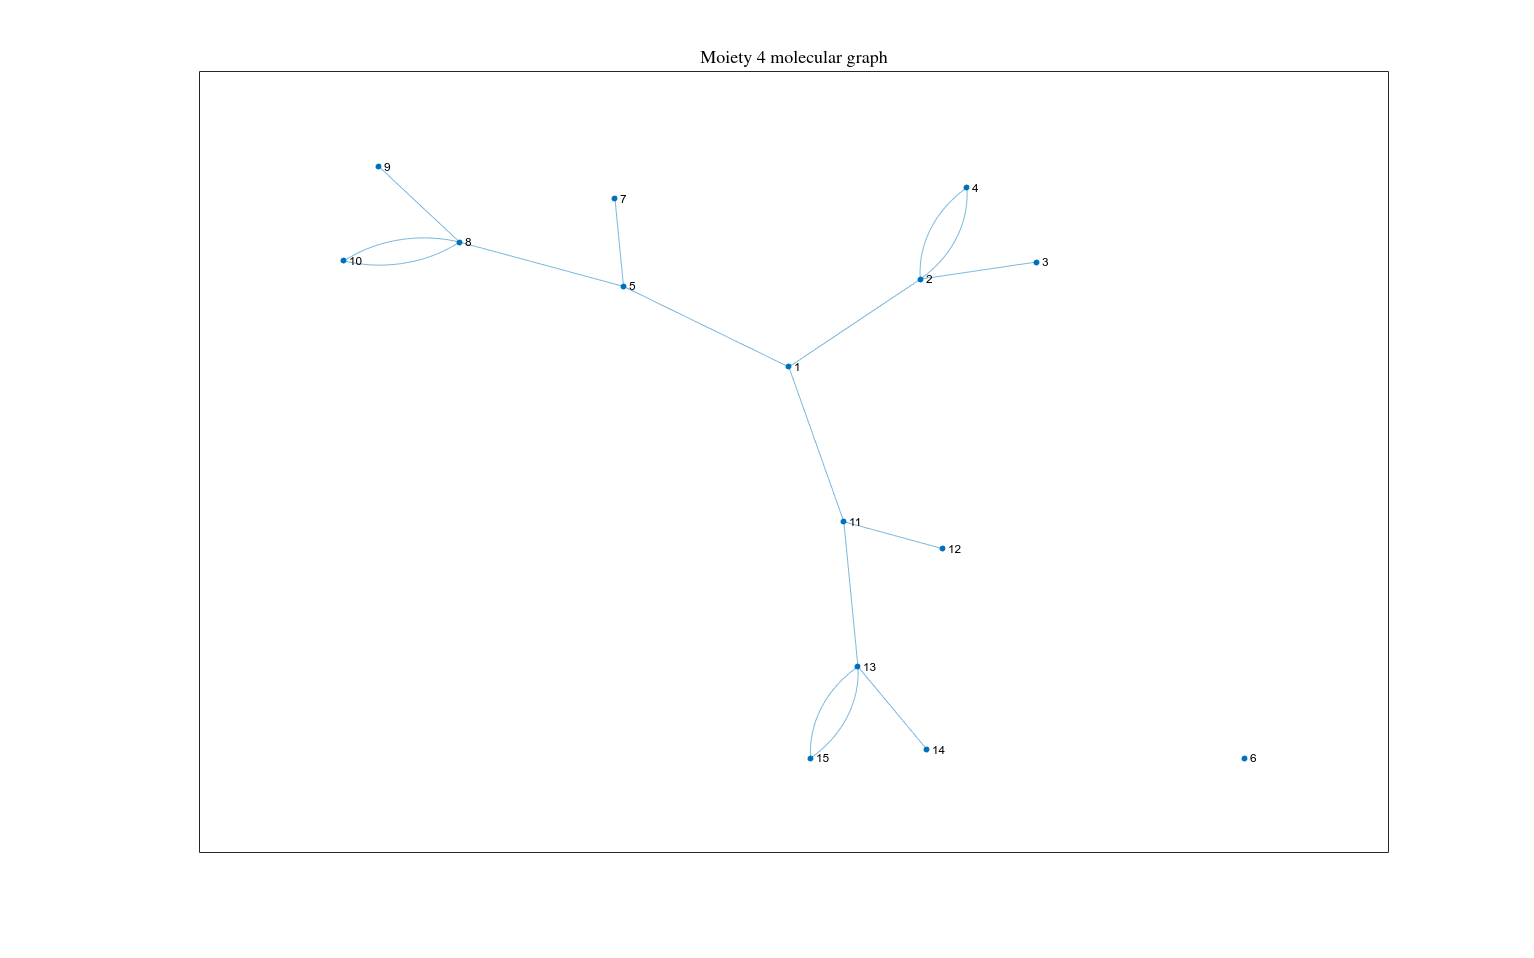

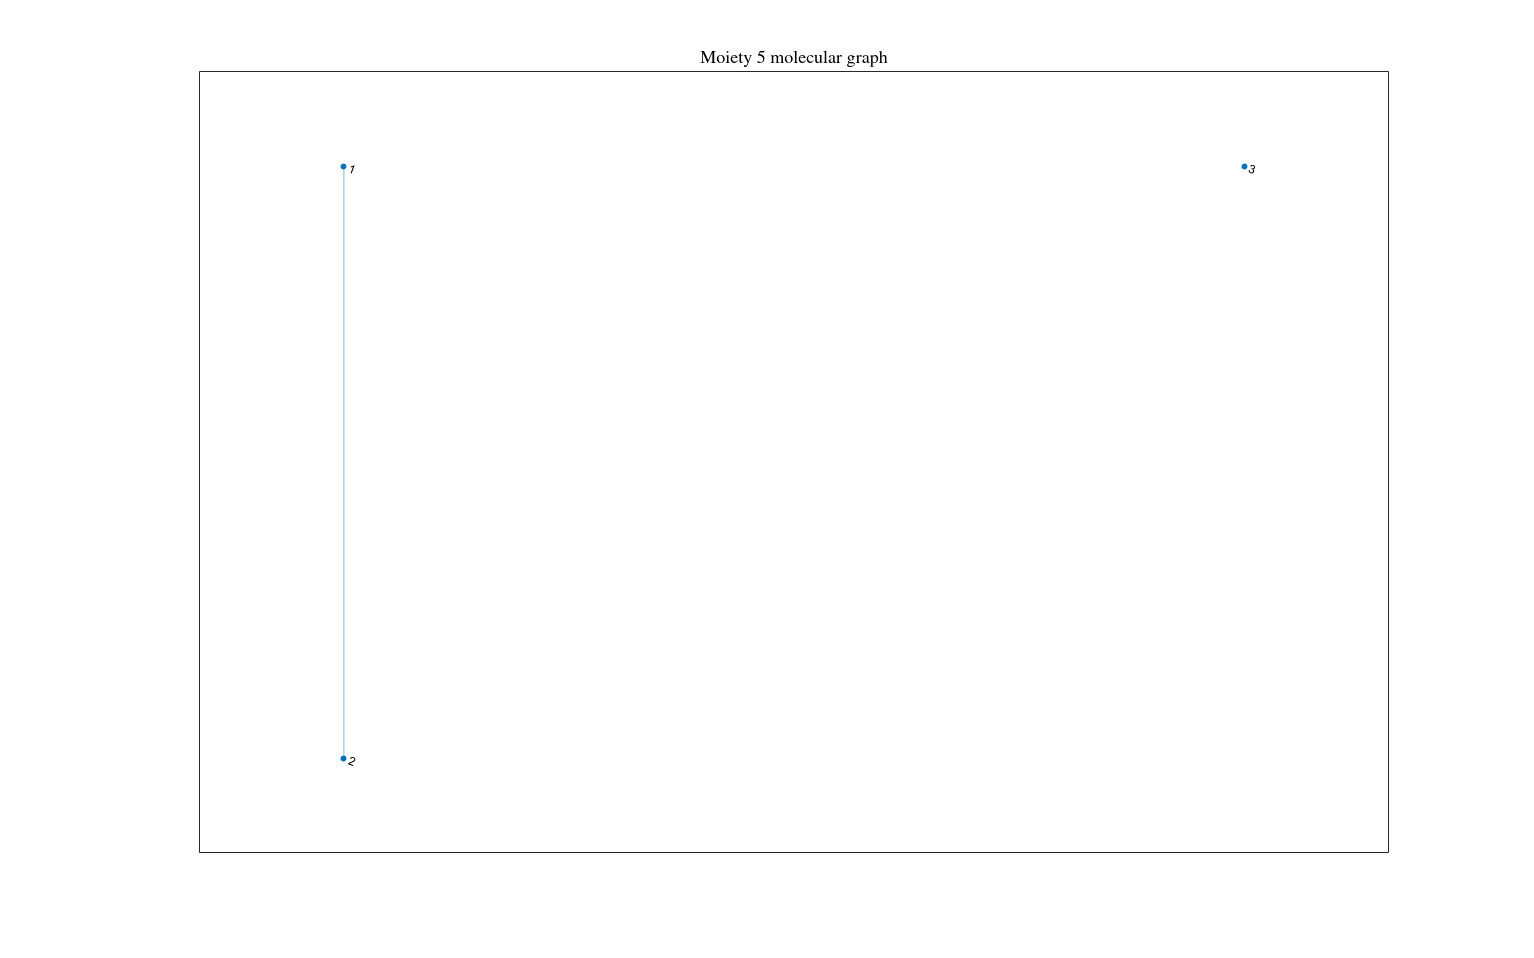

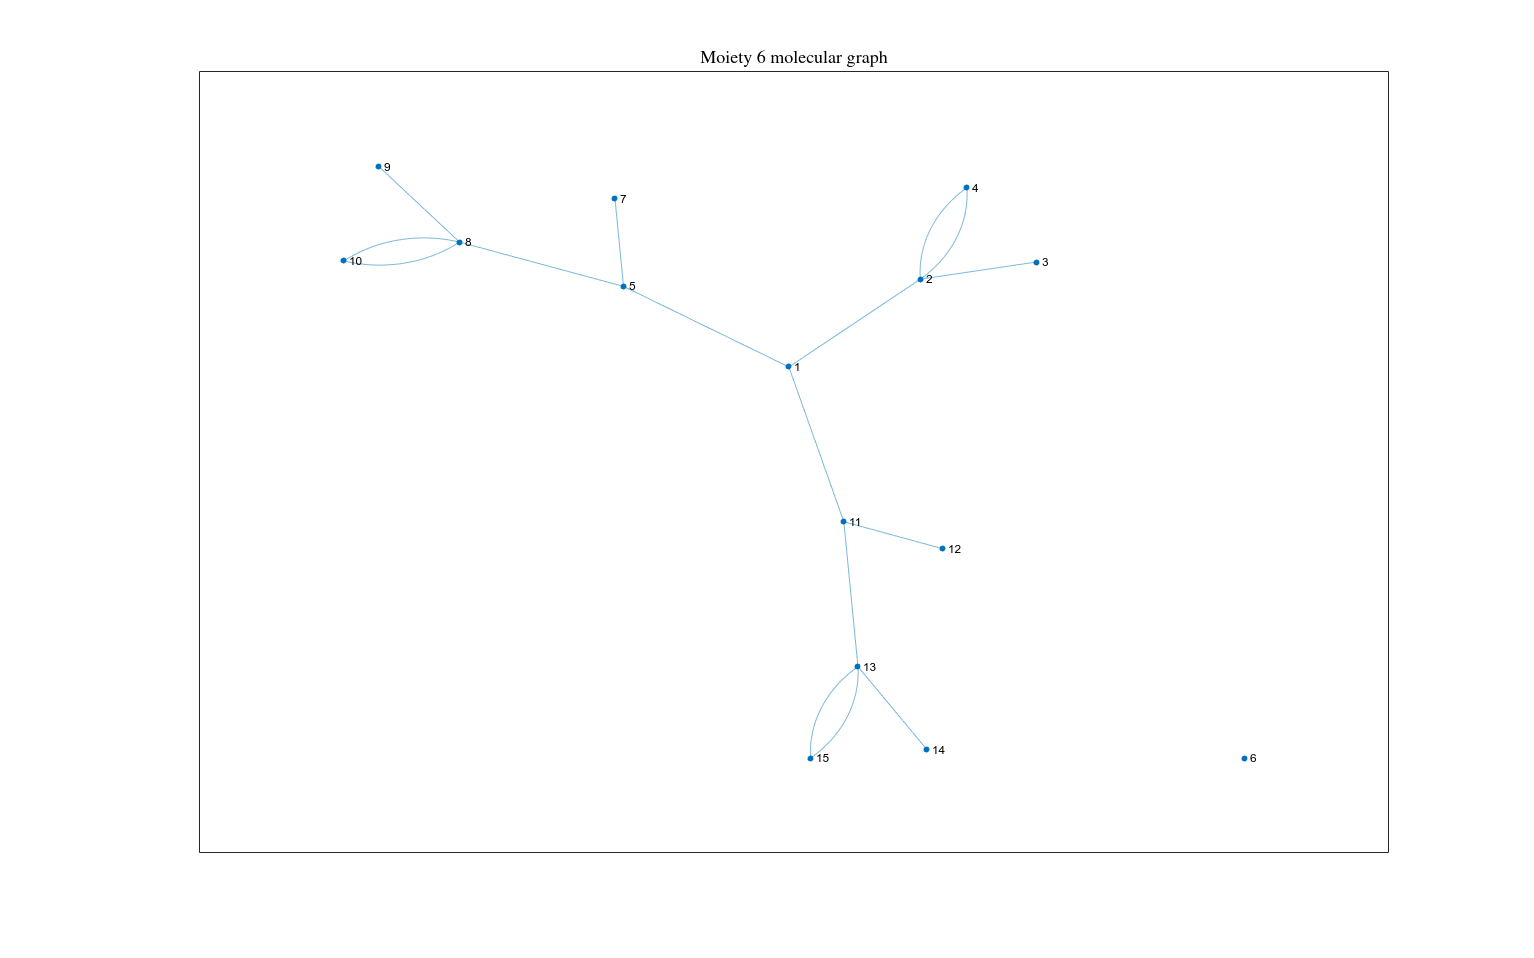

%% 10.4 Reacting moiety type summary (formed vs broken)

%% Reacting Moiety Summary 

rxnList = reacting.selectedReactionNames;
Condensed_RBG = reacting.Condensed_RBG;

nRxn = numel(rxnList);


summary = table('Size',[nRxn 3], ...
    'VariableTypes',["string","double","double"], ...
    'VariableNames',["Reaction","NumReactingBonds","NumCondensedEdges"]);

for k = 1:nRxn
    

Selected reactions covering reacting bonds:


    rxn = rxnList{k};

    {'ACONTm'}
    {'r0317' }



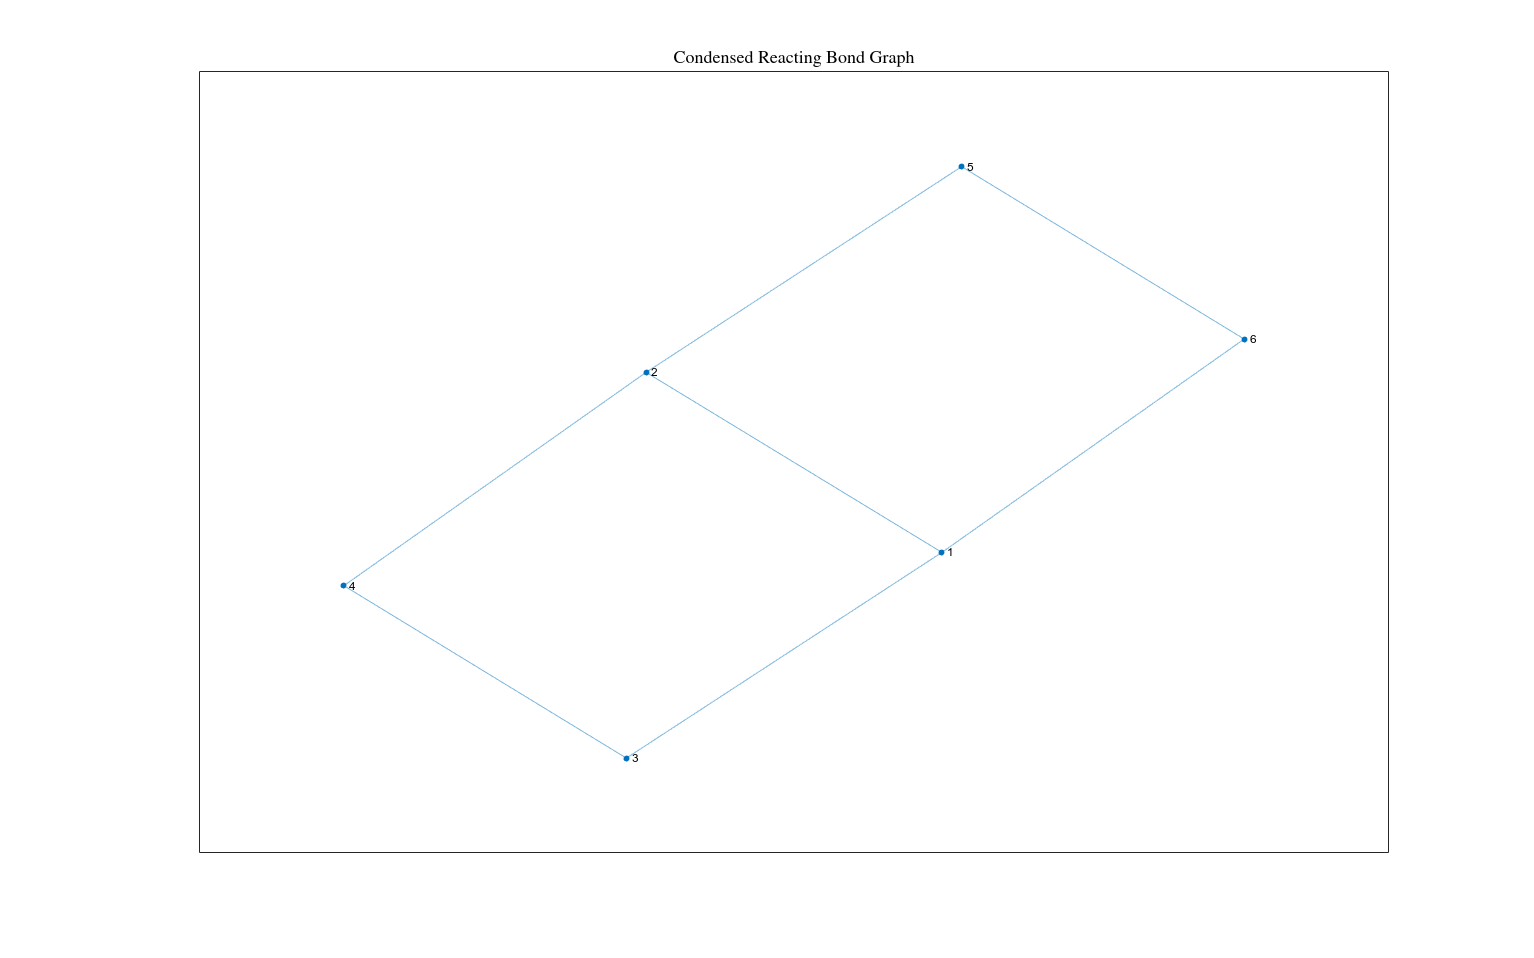

    
    % reacting bonds for this reaction
    bondSet = reacting.ReactMoietySets{k};
    
    summary.Reaction(k) = string(rxn);
    summary.NumReactingBonds(k) = length(bondSet);
    

    % Count unique condensed edges
    summary.NumCondensedEdges(k) = ...
        numedges(subgraph(Condensed_RBG, unique( ...
        Condensed_RBG.Edges.EndNodes(bondSet,:) )));
end

disp("Reacting moiety summary:")
disp(summary)

%% Optional: Bond formation vs cleavage (paper Section X)

[brokenBondsTable, formedBondsTable] = ...
    identifyConservedReactingSubgraphs(subModel, dATM, dBTM);

reacting.brokenBondsTable = brokenBondsTable;
reacting.formedBondsTable = formedBondsTable;

%% Reacting moiety formation vs cleavage summary


    Reaction    NumReactingBonds
    ________    ________________

    "ACONTm"           5        
    "r0317"            5        



rxnList = reacting.selectedReactionNames;
nRxn = numel(rxnList);

summaryFB = table('Size',[nRxn 4], ...
    'VariableTypes',["string","double","double","double"], ...
    'VariableNames',["Reaction","NumFormed","NumBroken","Total"]);

for k = 1:nRxn

    rxn = rxnList{k};
    
    nFormed = sum(strcmp(reacting.formedBondsTable.rxns, rxn));
    nBroken = sum(strcmp(reacting.brokenBondsTable.rxns, rxn));

    summaryFB.Reaction(k)  = string(rxn);
    summaryFB.NumFormed(k) = nFormed;
    summaryFB.NumBroken(k) = nBroken;
    summaryFB.Total(k)     = nFormed + nBroken;
end

disp("Reacting moieties (formed vs broken):")
disp(summaryFB)

%% Extraction of Reacting Bond Subgraphs
% In this step, we classify bond transitions into:
%   - Conserved bond subgraph (CBG)
%   - Reacting bond subgraph (RBG)
%
% This corresponds to the bond-level refinement described in
% Rahou et al. (2025), where reacting bonds are those not belonging
% to conserved bond patterns.
%
% The function returns tables of broken and formed bonds as well as
% the associated conserved and reacting atom/bond subgraphs.

Reacting moiety summary:


[brokenBondsTable, formedBondsTable, CAG, RAG, CBG, RBG] = ...

    Reaction    NumReactingBonds    NumCondensedEdges
    ________    ________________    _________________

    "ACONTm"           5                    7        
    "r0317"            5                    7        



    identifyConservedReactingSubgraphs(subModel,dATM,dBTM);

%
%% Construction of Reacting Moiety Tables
% For interpretability, we convert raw bond transition data into
% compact tables listing, for each selected reaction:
%   - Whether a bond is formed or broken
%   - The atom indices involved
%   - The chemical bond type (e.g. C-C, O-H)
%
% Artificial transition bonds (E–E) are removed to retain only
% chemically meaningful bond changes.

reacting = buildReactingMoietyTables(reacting, formedBondsTable, brokenBondsTable);

%%  Display of Reacting Moieties
%
% We now display, for each reaction selected by the minimum set cover,
% the corresponding reacting moiety — defined as the set of bonds
% that are formed or broken in that reaction.
%
% This provides a chemically interpretable view of the reacting structure.

displayReactingMoieties(reacting);

## 10.4 Reacting Moiety Graphs

%% 10.4 Reacting moiety graphs

for k = 1:length(reacting.ReactMoietyGraphs)

Reacting moieties (formed vs broken):


    figure

    Reaction    NumFormed    NumBroken    Total
    ________    _________    _________    _____

    "ACONTm"        2            2          4  
    "r0317"         2            2          4  



    plot(reacting.ReactMoietyGraphs{k})
    title(sprintf('Reacting moiety for reaction %s', ...
        reacting.selectedReactionNames{k}))
end

# 11. Moiety Graph Construction (Paper Section 7)

%% 11. Moiety graph

moietyGraph = createMoietyGraph(subModel, BG, arm);

figure
plot(moietyGraph,"EdgeLabel",moietyGraph.Edges.mets)
title('Moiety Graph')

# 12. Optional: Reduced Molecular Graphs

Reacting moieties summary:
    Reaction    NumFormed    NumBroken    Total
    ________    _________    _________    _____

    "ACONTm"        2            2          4  
    "r0317"         2            2          4  


=== Reacting moiety 1 (reaction ACONTm) ===
    BondChange    BondEndNodes    BondElmts              Bond                  rxns   
    __________    ____________    _________    _________________________    __________

     "formed"        4    34        "O-C"      "icit[m]#2#O#icit[m]#3#C"    {'ACONTm'}
     "formed"        4    35        "C-H"      "icit[m]#8#C#icit[m]#9#H"    {'ACONTm'}
     "broken"        3     4        "O-C"      "cit[m]#2#O#cit[m]#3#C"      {'A

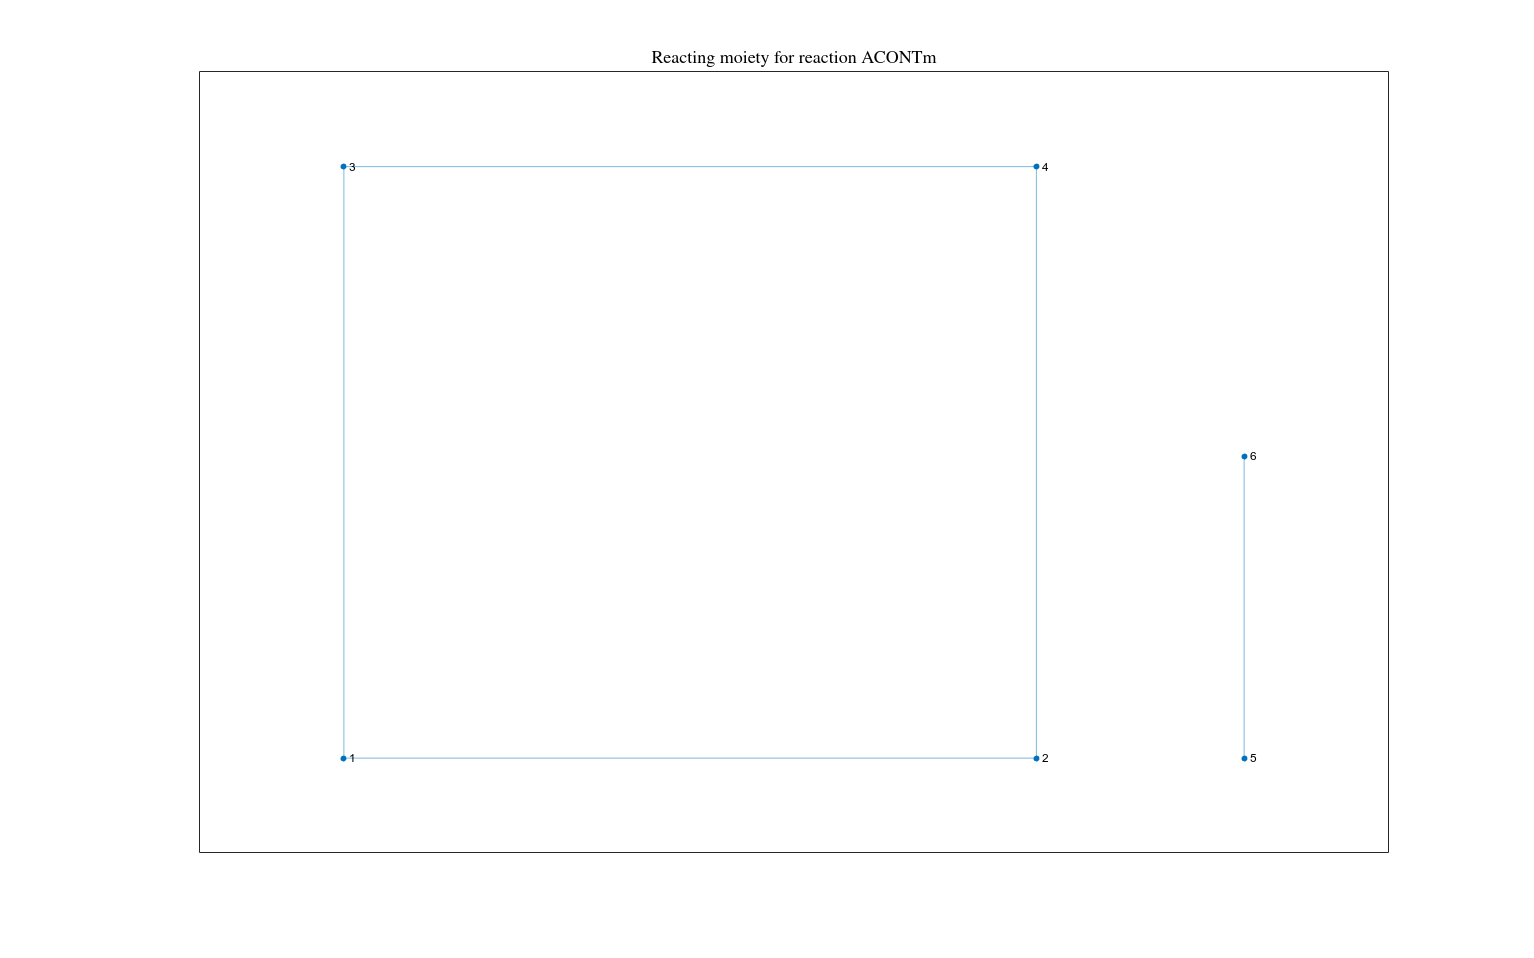

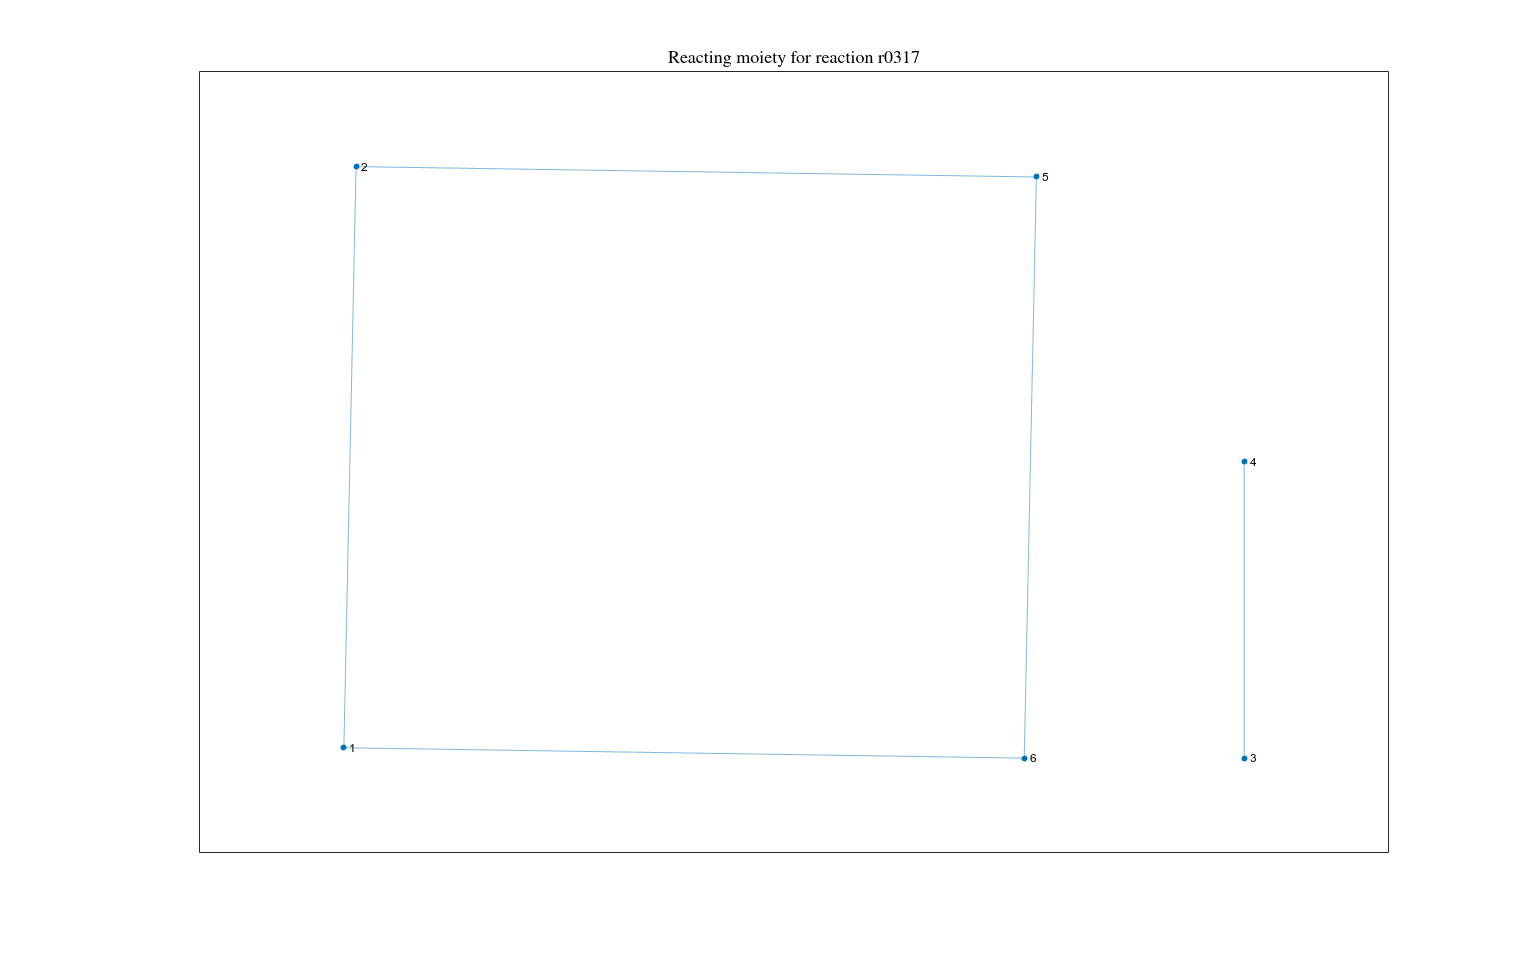

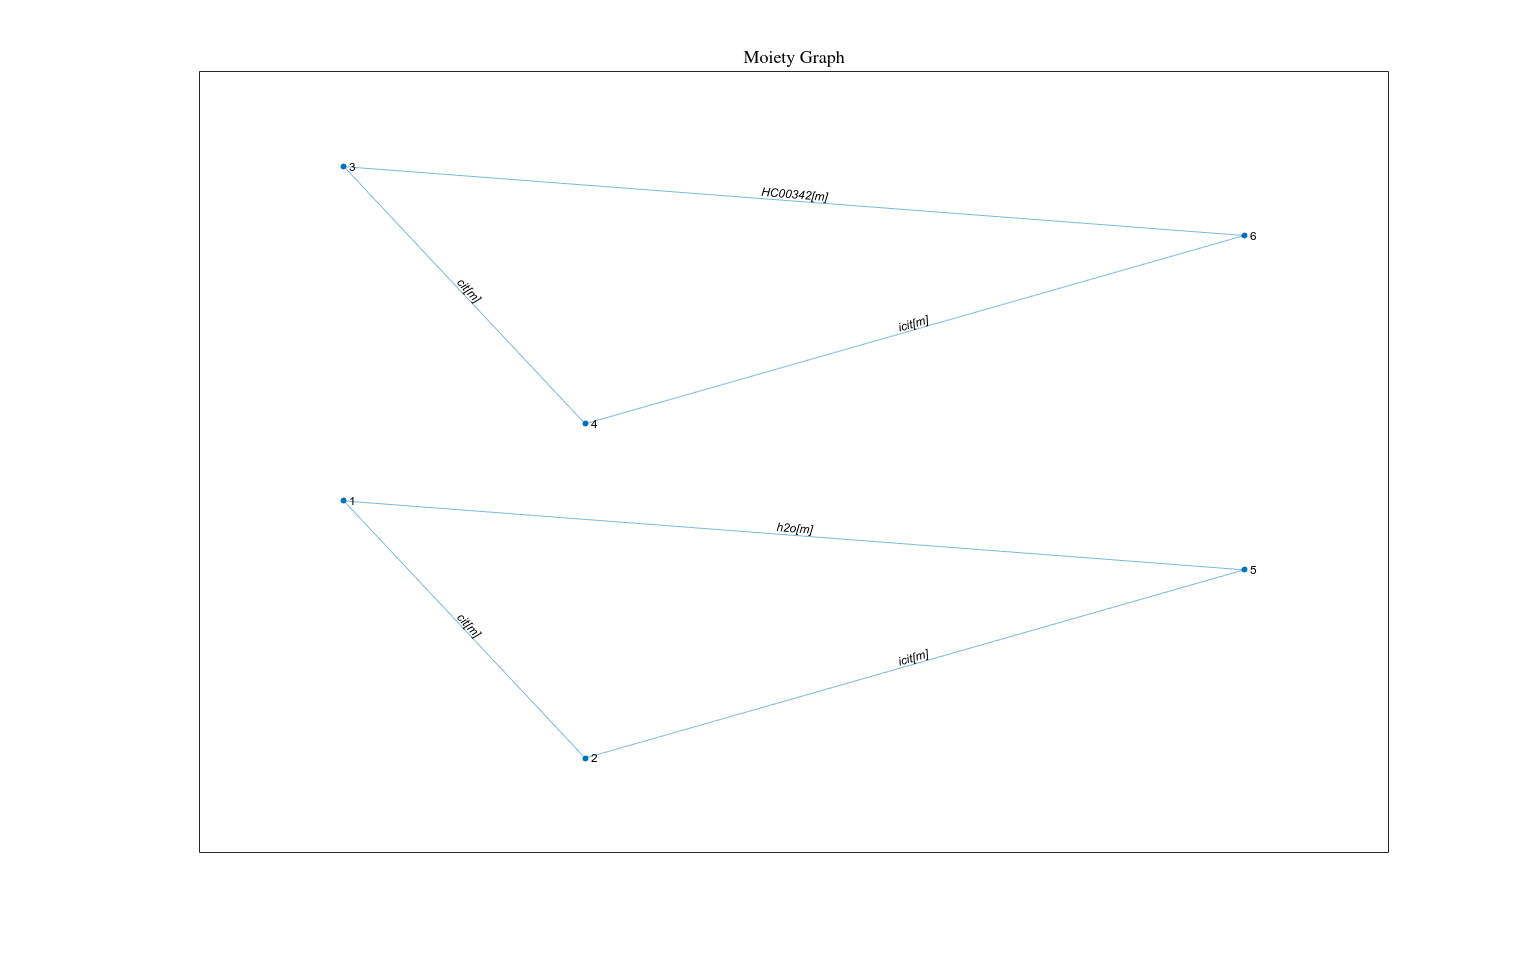

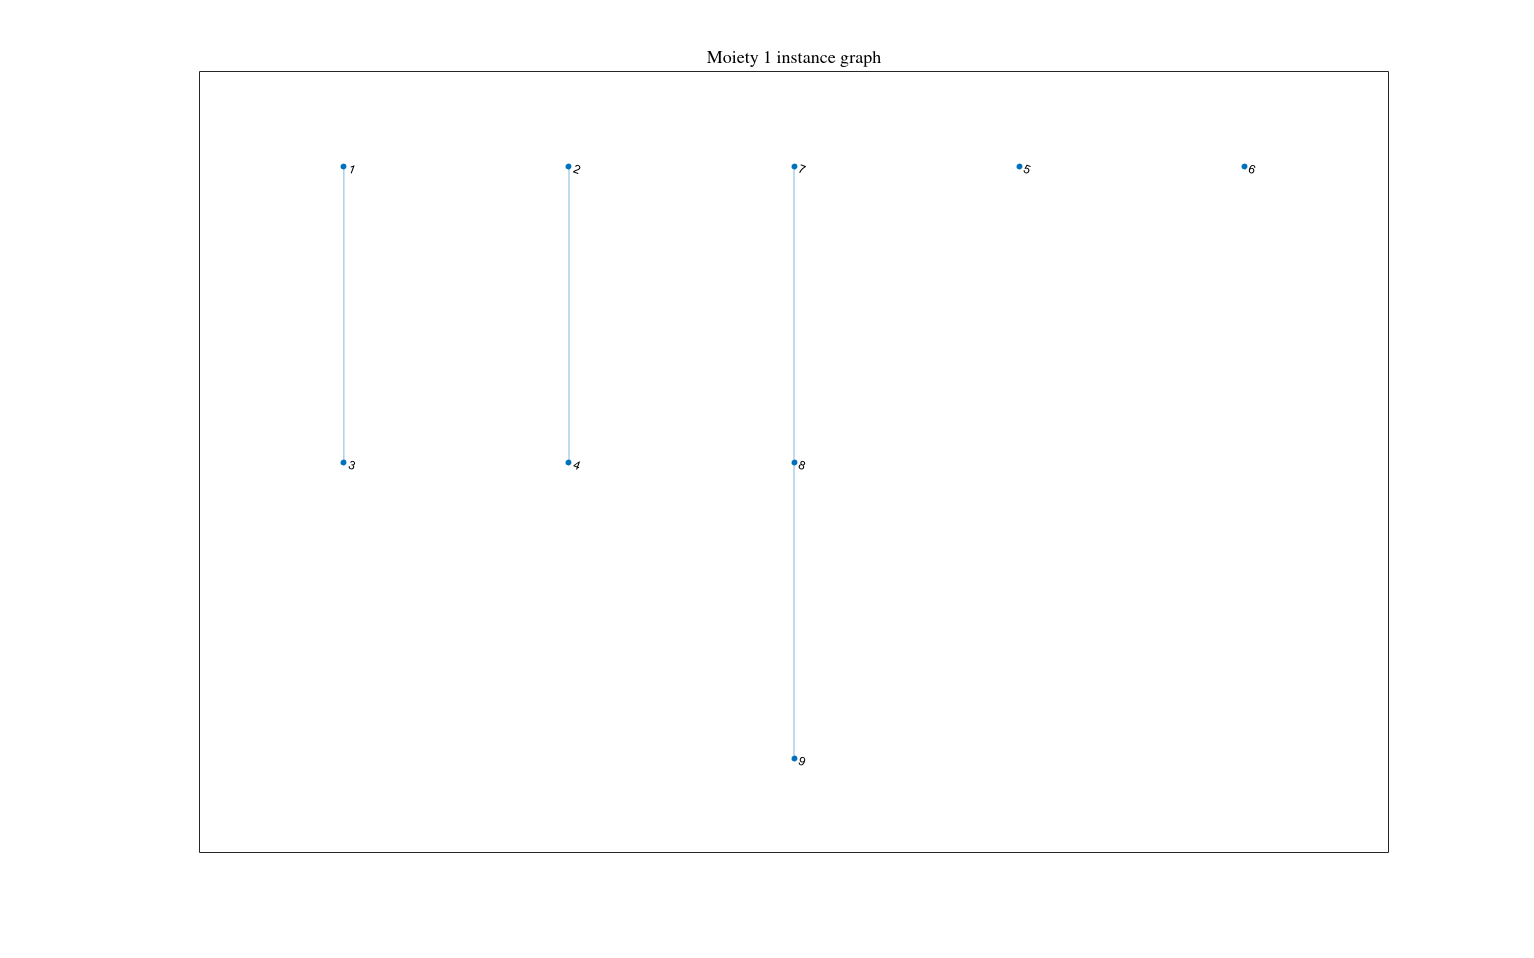

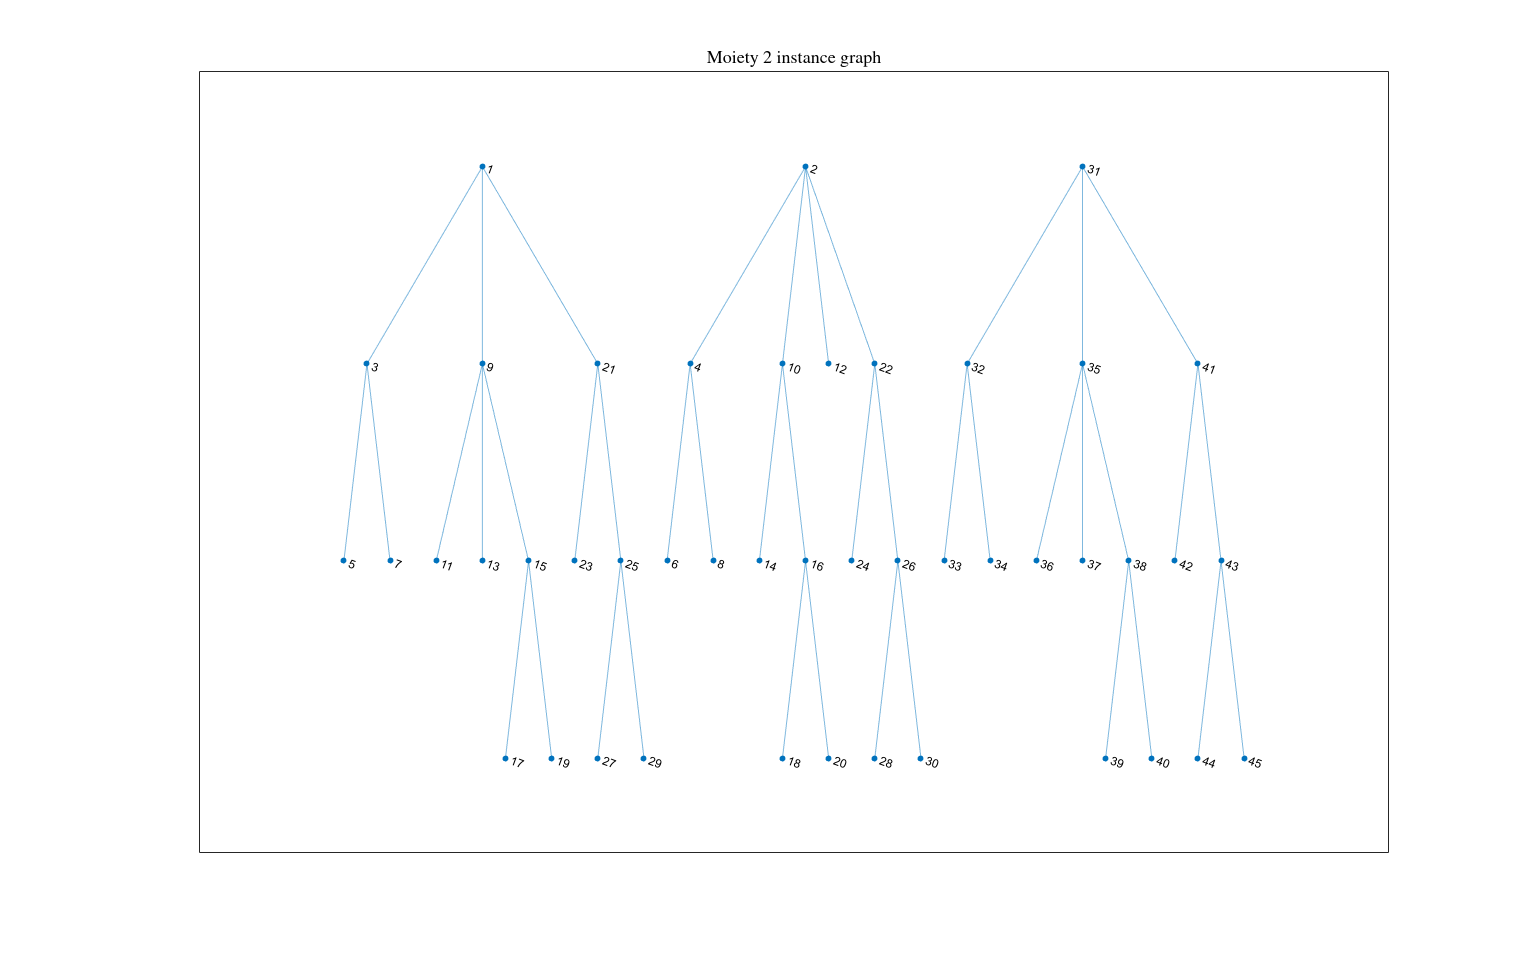

%% 12. Optional graph reduction

[MG, moietyMG, moietyInstanceG] = ...
    getMetMoietySubgraphs(subModel,BG,arm);

for i = 1:numel(moietyMG)
    figure
    plot(moietyMG{i})
    title(sprintf('Moiety %d instance graph', i))
end

# 13. References

Ghaderi et al. (2020)

Structural conserved moiety splitting of a stoichiometric matrix.

Journal of Theoretical Biology 499, 110276.

**Rahou et al. (2025)**

Characterisation of conserved and reacting moieties in chemical reactions.

Journal of Theoretical Biology.

[https://doi.org/10.1016/j.jtbi.2025.112348](https://doi.org/10.1016/j.jtbi.2025.112348)